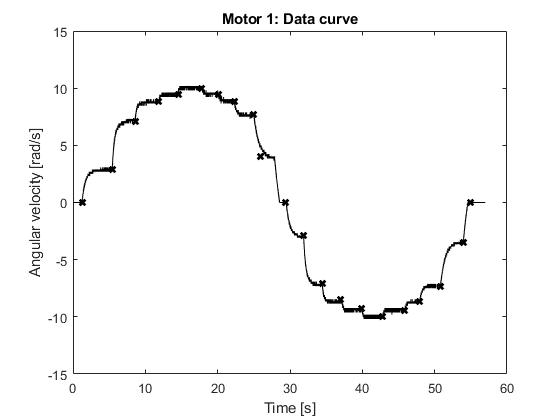

clear all
load Motor1

x=[];y=[];

x(1)=1.25; y0(1)=0;
x(2)= 5.44; y0(2)=2.885;
x(3)= 8.605 ; y0(3)= 7.116;
x(4)= 11.86 ; y0(4)= 8.847;
x(5)= 14.53; y0(5)= 9.424;
x(6)= 17.75;y0(6)=10;
x(7)=20.09;y0(7)=9.424;
x(8)= 22.27;y0(8)=8.847;
x(9)= 25.02;y0(9)=7.693;
x(10)=25.87; y0(10)= 4.03;
x(11)= 29.44; y0(11)=0;
x(12)=31.89; y0(12)= -2.885;
x(13)=34.45;y0(13)=-7.116;
x(14)= 37.03; y0(14)=-8.462;
x(15)= 39.9; y0(15)= -9.231;
x(16)= 42.8; y0(16)=-10;
x(17)=45.89; y0(17)= -9.424;
x(18)=47.94; y0(18)=-8.655;
x(19)= 50.83;y0(19)=-7.308;
x(20)=53.98; y0(20)=-3.462;
x(21)=55;y0(21)=0;
plot (X_Value,ControlOutput,'k')
hold on
plot(x,y0,'xk','LineWidth',2)
xlabel('Time [s]')

ylabel('Angular velocity [rad/s]')
title('Motor 1: Data curve')
hold off


tamano=length(x)-1;
escalon=cell(tamano,2);
for i=1:tamano
    aux=(ControlOutput(x(i)/0.005));
    escalon{i,2}= ControlOutput(x(i)/0.005:x(i+1)/0.005)-aux;
    escalon{i,1}= linspace(0,x(i+1)-x(i),length(escalon{i,2}));
end
k=[];
Tao=[];
Wc=[];
idx=[];
Funcion=cell(tamano,1);
Filtro=cell(tamano,1);

for i=1:tamano
    k(i)=escalon{i,2}(end)-escalon{i,2}(1);
    [na,aux1]=min(abs(escalon{i,2}-0.63*k(i)));
    [na,aux2]=min(abs(escalon{i,2}-0.28*k(i)));
    Tao(i)=1.5*(escalon{i,1}(aux1)-escalon{i,1}(aux2));
    Wc(i)=Tao(i)/10;
    Funcion{i,1} = tf(k(i),[Tao(i),1]);
    
%     filtro
    Filtro{i,1} = tf(1,[Wc(i),1]);
end

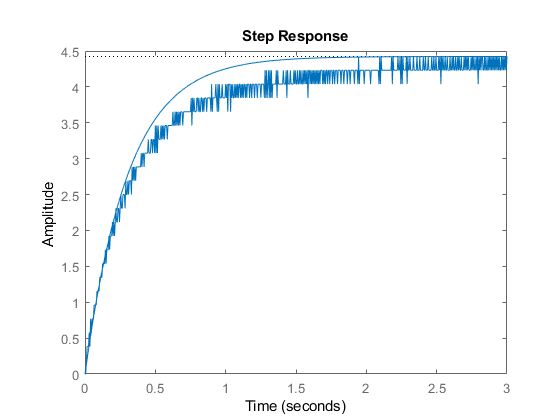

graficar=2;
plot(escalon{graficar,1},escalon{graficar,2})
hold on
step(Funcion{graficar},3)
hold off


T=0.005;
% 

Filtrodigital=cell(tamano,1);
numfiltrodigital=zeros(tamano,1);
denfiltrodigital=zeros(tamano,1);

for i=1:tamano
    Filtrodigital{i,1} = c2d(Filtro{i,1},T);
    
    numfiltrodigital(i)=Filtrodigital{i}.num{1}(end);
    denfiltrodigital(i)=Filtrodigital{i}.den{1}(end);
end


aplicando el filtro

ecuacion en diferencias

y_k=num*x_k-1+den*y_k-1

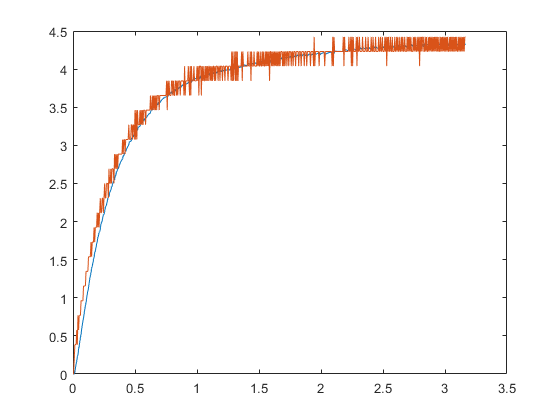


Y=cell(tamano,1);

for j=1:tamano
y=[0];

aux1 = escalon{j,1};
aux2 = escalon{j,2};

for i=2:length(aux2) %para y valor actual comienza en 2
    y(i)=numfiltrodigital(j)*aux2(i-1)-denfiltrodigital(j)*y(i-1);
end

Y{j}=y;
end

plot(escalon{graficar,1},Y{graficar})
hold on
plot(escalon{graficar,1},escalon{graficar,2})  % al aplicar el filtro se agrega un retardo

Errores

    Error2medio=(Y{graficar}'-escalon{graficar,2})'*(Y{graficar}'-escalon{graficar,2})/length(escalon{graficar,1});
    for i=1:tamano
    Error2medios(i)=(Y{i}'-escalon{i,2})'*(Y{i}'-escalon{i,2})/length(escalon{i,1});
    end

% Tabla=cell(tamano,5);

% for i=1:tamano
%     Tabla{i,:} = table(i,mat2str(Funcion,mat2str([Funcion{i}.den{1}]),Wc(1),Error2medios(i)));
% end



for i=1:tamano
    k_new(i)=Y{i}(end)-Y{i}(1);
    [na,aux1]=min(abs(Y{i}-0.63*k_new(i)));
    [na,aux2]=min(abs(Y{i}-0.28*k_new(i)));
    Tao_new(i)=1.5*(Y{i}(aux1)-Y{i}(aux2));
    
end


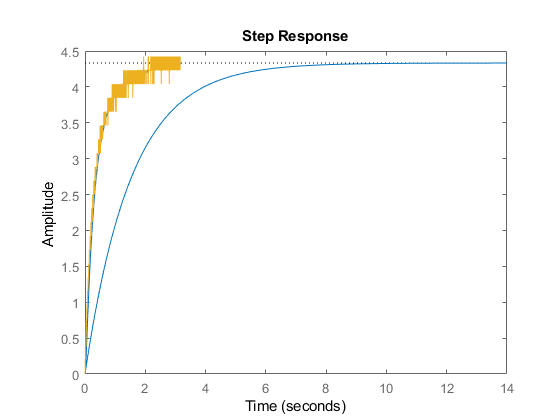

step(k_new(graficar),[Tao_new(graficar-1),1]);
hold on
plot(escalon{graficar,1},escalon{graficar,2}) 